irr_ej_01:

Version: 001

Date:    2020/04/21

Author:  Rodrigo Gonzalez <rodralez@frm.utn.edu.ar>

URL:     https://github.com/rodralez/td3

URL:     https://github.com/rodralez/control

clear
clc
close all

## a) Señal de entrada

fs = 2000;
fn = 100;

dt_s = 1/fs;

t = 0 : dt_s : 1/fn * 6;

signal = sin(2 * pi * fn * t);

## b) Señal con ruido

snr = 15;

[signal_n, var_n] = my_noise (signal', snr);

## c) Filtro Leaky Integrator

% a(1) * y(n) = (1 - lambda) * x(n) - lambda * y(n-1)

lambda = 0.7;

b1 = 1 - lambda;
a1 = 1;
a2 =  -lambda;
A = [a1 a2];
B = b1;

## d) Respuesta en frecuencia

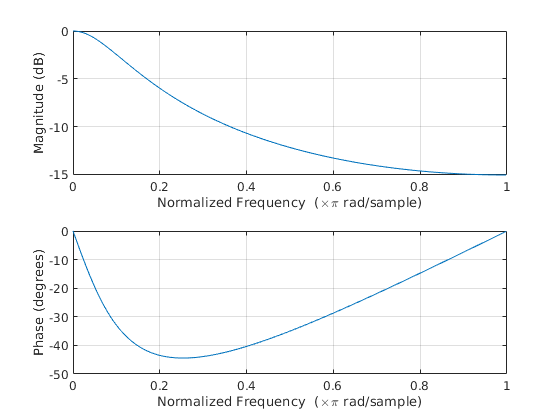

figure

freqz(B , A )


% Frecuencia de corte

format bank
fco = -log(lambda)/pi * fs

fco =         227.07

## e) Plano Z

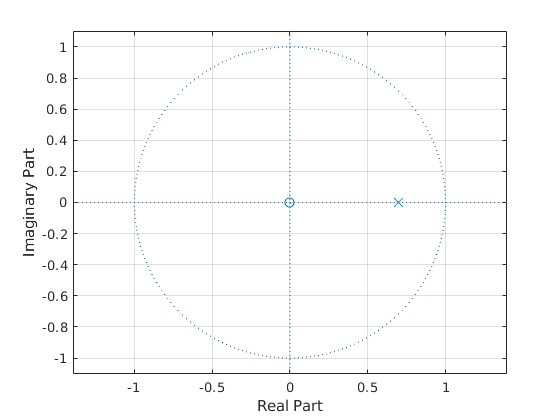

figure
zplane(B , A )
grid on

## f) Filtrado LI

signal_li = filter(B, A, signal_n);

## g) Respuesta en el dominio del tiempo

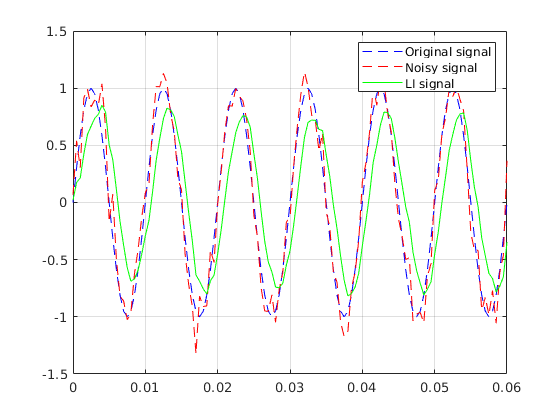

figure
plot(t, signal, '--b')
hold on
plot(t, signal_n, '--r')
plot(t, signal_li, '-g')
grid on
hold off
legend('Original signal','Noisy signal','LI signal')

## h) Respuesta en el dominio de la frecuencia

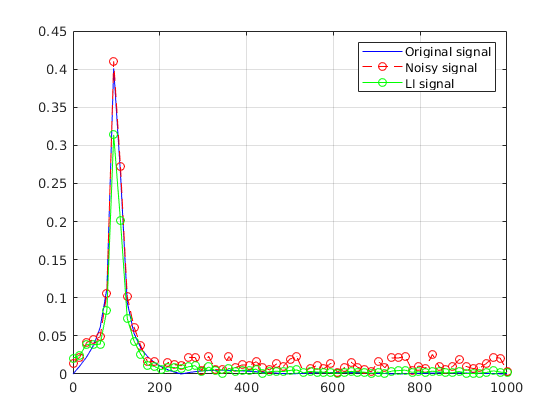

[f, m] = my_dft(signal, fs);
[fns, m_ns] = my_dft(signal_n, fs);
[fma, m_ma] = my_dft(signal_li, fs);

figure
plot(f, m, '-b')
hold on
plot(fns, m_ns, '--or')
plot(fma, m_ma, '-og')
hold off
grid on
legend('Original signal','Noisy signal','LI signal')